# `Galileo's Projectile Motion `  

Previously, we used Tracker software to analyze the trajectory of a projectile ball. We computed the value of gravitational acceleration through fitting a linear function of Vy vs t. We could do this, because in the absence of air friction we can obtain closed form solutions for the velocity and position of the ball in x and y directions: 


$$\begin{array}{l}
V_y \left(t\right)=-g\;t+V_y \left(0\right)\;\;\;\\
\Rightarrow y\left(t\right)=\int V_y \left(t\right)\textrm{dt}=-\frac{1}{2}g\;t^2 +V_y \left(0\right)t+y\left(0\right)\\
\\
V_{x\;} \left(t\right)=V_x \left(0\right)\;\;\;\\
\Rightarrow \;x\left(t\right)=V_x \left(0\right)\;t+x\left(0\right)
\end{array}$$
  

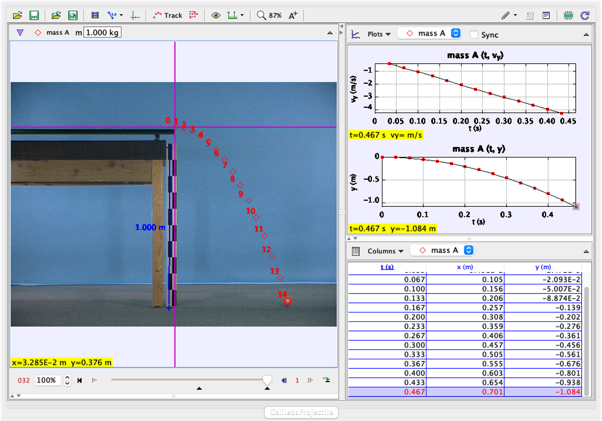

In most interesting and applied scenarios, however, these closed form analytical solutions cannot be obtained, and one needs to solve the equations of motion numerically through programming.  

# `Activity: Simulate the ball's falling motion in the absence of friction` 

The goal of this activity is to simulate the ball's movement and compare the simulation results to the actual results from Tracker.

## `Task 1: `

###  1`. Definitions:`

            Is this a Stochastic or Determininstic model?

Deterministic

            Is this a Dynamic or Static model?

Dynamic

            Is this a Continuous or Discrete model?

Continuous

### `2. Analyze the problem`

              What is the question we are trying to solve? 

Track the trajectory of a ball that is falling.

###         `2. ``Formulate a Model`

            *(a) Gather information and data *

We've done that already using Tracker

            *(b) Discuss the simplifying assumptions. *

No air resistance.

            (c) *Write down the variables and units. *

*t: time (s) x: horizontal distance (m) y: vertical distance  (m) Vx: x velocity (m/s) Vy: y velocity (m/s) dt: change in time (t) g: gravity (m/s^2)*

           *(d) and (e) Establish relationship between variables & Determine equations and functions. *

                These are provided for you below in the y dimension.

             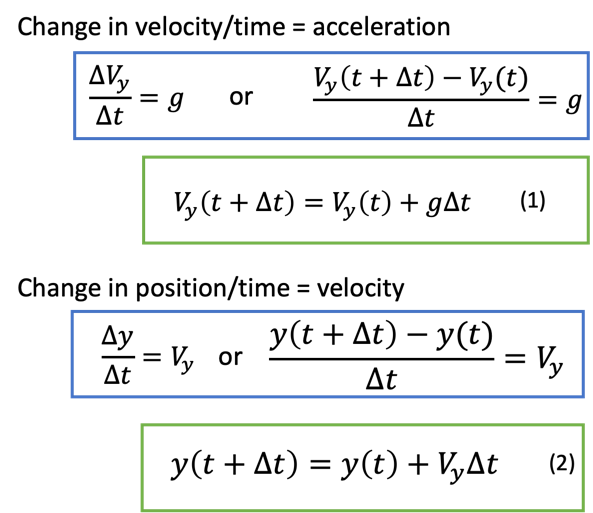

                Looking at equations (1) and (2) above, what are the corresponding equations for the x dimension? Remember that there is no gravity (g) in the x dimension. Write the equations below (use Insert / Equation to write these equations):


$$V_x \left(t+\Delta t\right)=V_x \left(t\right)$$



$$x\left(t+\Delta t\right)=x\left(t\right)+V_x \Delta t$$


## `Task 2: `

You will use the discretized equations (such as to eqs 1,2 above) to determine the velocity and position in x,y directions after one timestep t=dt=0.01 seconds. 

The initial conditions that we will use are:


$$V_{\textrm{x0}} =0\ldotp 15\;\left(\frac{m}{s}\right),{\;\;\;\;\;\;\;\;\;\;\;V}_{\textrm{y0}} =0\;\left(\frac{m}{s}\right),\;\;\;\;\;\;\;x_0 =0\;\left(m\right),\;\;\;\;\;\;\;\;\;\;\;y_0 =1\ldotp 1\;\left(m\right)$$
 

Note that this is a little different from when we used Tracker, because in that case, we defined our coordinate origin at point where the ball launched off of the table. Here, we are defining the coordinate origin at the floor. According to the Tracker movie snapshot above, this is 1.1m below the point where the ball launched off of the table. Therefore, y0=1.1m.

Write code below to compute values for  x1,y1,Vx1,Vy1 at time t=dt=0.01, based on the initial values of x0,y0,Vx0,Vy0.

clc;clear;%Clean the workspace
close all; %Close all the existing figures 

%Initial Conditions 
Vx0=0.15; % (m/s) Initial condition for velocity in x-direction
Vy0=0.0;  % (m/s)Initial condition for velocity in y-direction 
x0=0.0;  % (m)Initial condition for position in x-direction
y0=1.1;  % (m)Initial condition for position in y-direction
dt=0.01; %(s); delta t used in the simulations to approximate the derivatives
g=-9.8; % (m/s^2)

% Your code begins here:
Vx1 = Vx0;
Vy1 = Vy0+g*dt;
x1 = Vx0*dt+x0;
y1 = .5*g*(dt)^2 + Vy0*dt+y0;

## `Task 3: `

- Repeat the same process and write code below to determine values for  x2,y2,Vx2,Vy2 at time t=2*dt=0.02, based on the previous values of x1,y1,Vx1,Vy1 that were computed in task 2 above.

% Your code begins here:
Vx2 = Vx0

Vx2 = 0.1500

Vy2 = Vy0+g*dt*2

Vy2 = -0.1960

x2 = Vx0*dt*2+x0

x2 = 0.0030

y2 = .5*g*(dt*2)^2 + Vy0*dt*2+y0

y2 = 1.0980

## `Task 4:`

- Using the equations from tasks 2,3, write code using a for loop to calculate the velocity and the position for the first 40 time intervals, each separated by $\Delta t=0\ldotp 01\;\;\textrm{seconds}$. We refer to dt=0.01 as the timestep of our model. 

**Notes: **

- You will need to create 1D arrays for x, y, Vx, Vy, each of dimension Nsteps=40. These will store the all the values of **x,y, Vx, Vy** at all timesteps. The code should look something like this:

- Then, you need to assign the initial conditions as the values of the first element of your array. The code should look something like this:

- Finally, you will use the equations from tasks 2,3 that calculated x,Vx,y,Vy from tasks 2,3. Put these equations into a "for" loop. But these values are all arrays for this task, so you will need to make some changes, computing x(t+1) based on the value of x(t), etc. Look back at your bikeshare code to remind yourself of how you did something similar in that simulation.

- Also, think about the parameters in the "for" loop. If you include "for i=1:Nsteps" then on the last time through the for loop, i+1 will be Nsteps+1. This is one extra step than I've asked you do to. So the loop parameters should be "for i=1:Nsteps-1".

clc; clear; %Clean the workspace
close all; %Close all the existing figures 

%Initial Conditions 
Vx0 = 0.30; % (m/s) Initial condition for velocity in x-direction
Vy0 = 0.0;  % (m/s)Initial condition for velocity in y-direction 
x0 = 0.0;  % (m)Initial condition for position in x-direction
y0 = 1.1;  % (m)Initial condition for position in y-direction
dt = 0.01; %(s); delta t used in the simulations to approximate the derivatives
g = -9.8; % (m/s^2)
Nsteps = 40; %Number of time-steps 

% Your code begins here, starting with the initialization described in the
% notes above
x=zeros(Nsteps, 1);
y=zeros(Nsteps, 1);
Vx=zeros(Nsteps, 1);
Vy=zeros(Nsteps, 1);
x(1) = x0;
y(1) = y0;
Vx(1) = Vx0;
Vy(1) = Vy0;

for i = 1:Nsteps
    Vx(i) = Vx0;
    Vy(i) = Vy0+g*dt*i;
    x(i) = Vx0*dt*i+x0;
    y(i) = .5*g*(dt*i)^2 + Vy0*dt*i+y0;
end

## `Task 5: `

- Plot the variations of velocity and position in both directions as a function of time in 4 different figures i.e (x(t) vs t,  vx(t) vs t, y(t) vs t, vy(t) vs t)

- You will need to generate an array for time in order to plot these values vs time. There are several ways to do this: using the colon operator, using the linspace function, or by generating t(i+1) as a function of t(i) in the for loop. Any of these methods are fine!

- Put relevant titles for the plots and add x-axis and y-axis labels. 

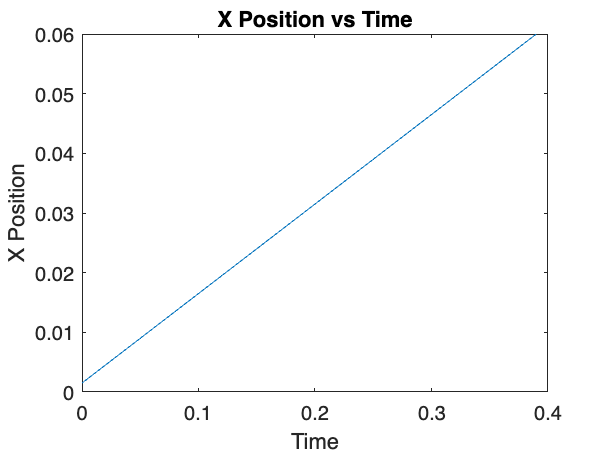

%Plot the graphs here -- run this section right after running task 4
t = 0:dt:(Nsteps-1)*dt;
plot(t, x)
title("X Position vs Time")
xlabel("Time")
ylabel("X Position")

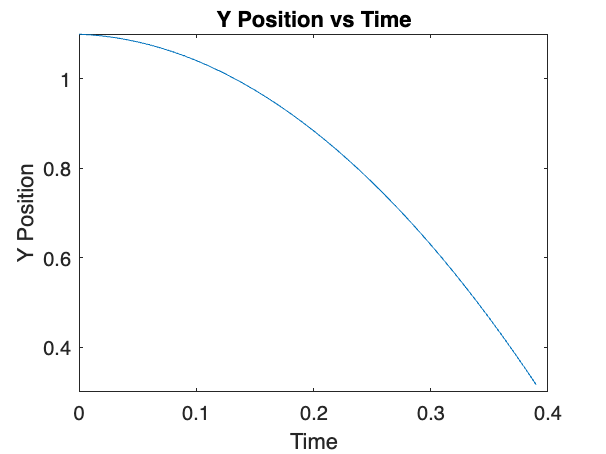

plot(t, y)
title("Y Position vs Time")
xlabel("Time")
ylabel("Y Position")

## `Task 6: `

- Rewrite the code from tasks 4,5 replacing the ***for*** loop with a ***while*** loop. The condition of the ***while*** loop should repeat the loop until the ball hits the ground ($\left.y\le 0\right)$. Report the total time. 

- Confirm this by plotting the position curve. 

- As in task 5, your figures should have titles and you should label the x and y axes

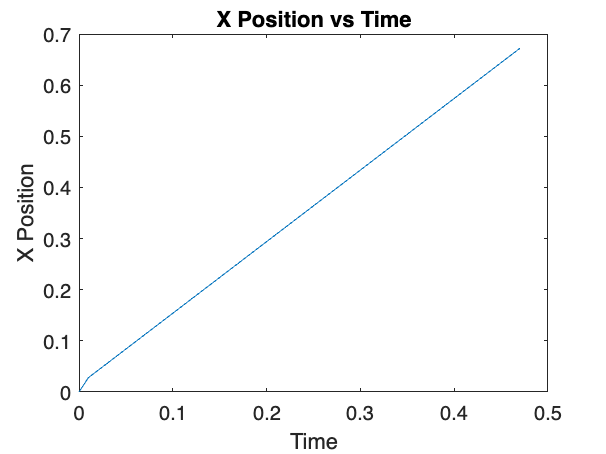

clc; clear; %Clean the workspace
close all;  %Close all the existing figures 

%Initial Conditions 
Vx0=1.4; % (m/s) Initial condition for velocity in x-direction
Vy0=0.0;  % (m/s)Initial condition for velocity in y-direction 
x0=0.0;  % (m)Initial condition for position in x-direction
y0=1.1;  % (m)Initial condition for position in y-direction
dt=0.01; %(s); delta t used in the simulations to approximate the derivatives
g=-9.8; % (m/s^2)
Nsteps=100; %Number of time-steps 

% Your code begins here: 

i=1;
x(i) = x0;
Vx(i) = Vx0;
Vy(i) = Vy0;
y(i) = y0;

while y(i) >= 0
    i = i+1;
    Vx(i) = Vx0;
    Vy(i) = Vy0+g*dt*i;
    x(i) = Vx0*dt*i+x0;
    y(i) = .5*g*(dt*i)^2 + Vy0*dt*i+y0;
    if y(i) < 0
        time = dt*i;
        totalSteps = i;
    end
end

t = 0:dt:(totalSteps-1)*dt;
plot(t, x)
title("X Position vs Time")
xlabel("Time")
ylabel("X Position")

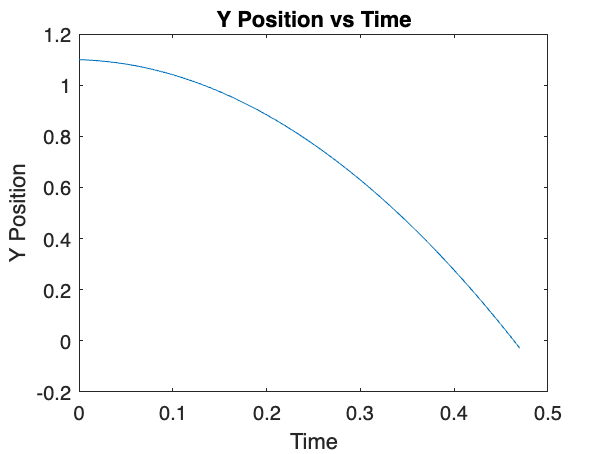

plot(t, y)
title("Y Position vs Time")
xlabel("Time")
ylabel("Y Position")

## `Task 7: Compare the predictions against experimental results from tracker.`

**[1]  Note: **To make this comparison, you need to redefine your coordinate axis in Tracker, such that y=0 defines ground level. So, the origin should be at the bottom of your calibration stick.  Track your ball in x and y. 

**[2] **   Make sure that the data window has 3 columns of data: t,x,y. To export this data into MATLAB, first "Export" the data in Tracker by clicking: "file", "export", "Data file", and select All Cells and change the delimeter to "comma".  

You should save this with a ".csv" extension (comma separated values).

What you get should look like this depending on if you are opening it in Excel or text editor :

**Excel                                                                                 Text Editor **

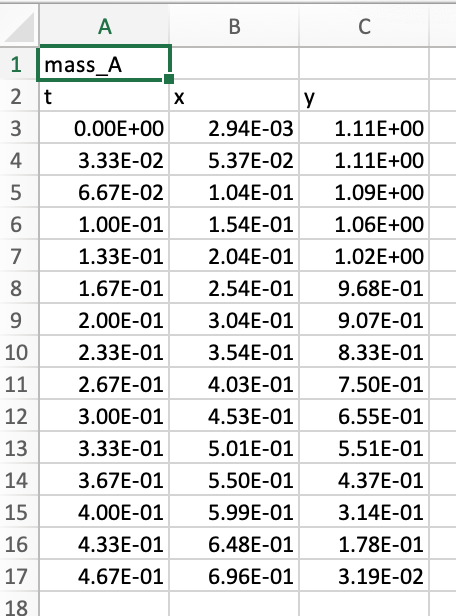        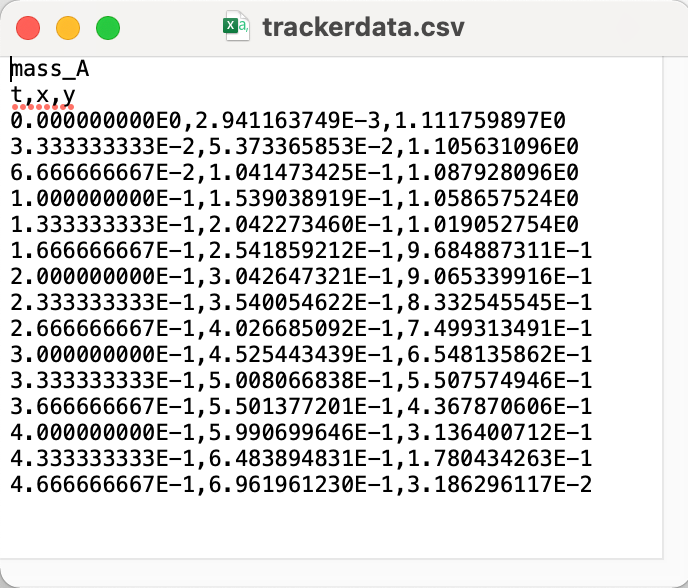

**[3]**    Erase the first two lines that contain text, so that you are left with only numbers. Save this as another file, say "**trackerdata.csv**" in the same folder as your MATLAB file. Be sure that the "Current Folder" for the Matlab workspace is set to this folder as well. Otherwise, Matlab won't be able to find the file.

**Note:** Extracting the data from the original file that includes text is certainly possible. It would only require a bit more programming. We have chosen the easiest route here i.e. removing the text. 

**[4]**    At this point you can load the whole file as a single 2D array with three columns and some number of rows depending on the number of time intervals. 

The command for this is 

Data = load('trackerdata.csv');

- This reads the data from the file into an array called "data", which contains three columns: **t, x, y**. So, we can extract the experimental values for **t**, **x**, and **y** using the following commands:

t_exp=Data(:,1);
x_exp=Data(:,2);
y_exp=Data(:,3);

**[5]**   Now plot **x** and **y** data from both experiments and computations as a function of time on a single plot to compare them. You should have a legend that identifies the two curves on each plot as simulation and experimental results. And as in the above tasks, your figures should have titles and you should label the x and y axes. 

**Note:** For the x vs t graph, you should plot the experimental data, followed by "**hold on**", and then plot the simulation data followed by "**hold off**". This will plot both graphs on the same axes. Then repeat the same thing for the y vs t graph.

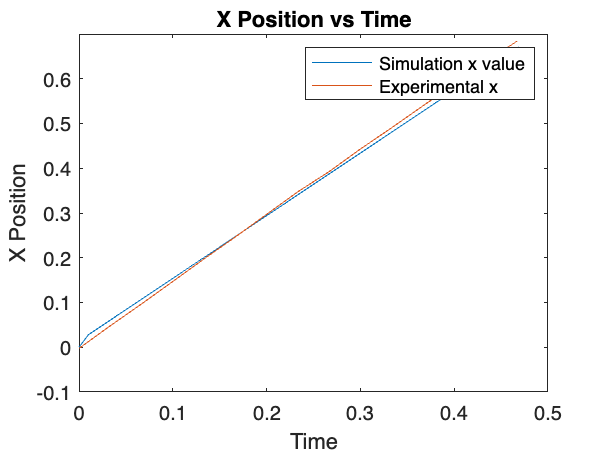

% Your code begins here:
plot(t, x, t_exp, x_exp)
title("X Position vs Time")
xlabel("Time")
ylabel("X Position")
legend("Simulation x value", "Experimental x")

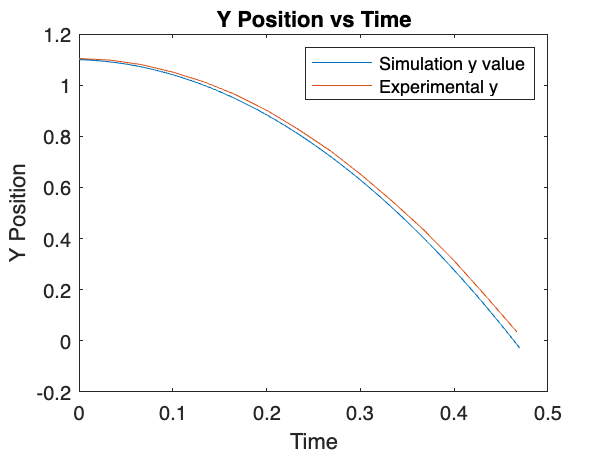

plot(t, y, t_exp, y_exp)
title("Y Position vs Time")
xlabel("Time")
ylabel("Y Position")
legend("Simulation y value", "Experimental y")

##   Task 8

Did the experimental graphs line up with the simulation graphs? If not, change the appropriate parameters in the initialization section of task 6, and rerun tasks 6 and 7 until you get the graphs to line up.

Describe below what changes that you needed to make to the initialization parameters. 

    The experimental and simulation data were not quite the same, but I was able to get them very close. For the x position I changed the x velocity until I was able to get very close to having them line up. 